# Legame spazio degli stati - funzione di trasferimento

Il controllo nello spazio degli stati è riscrivibile come funzione di trasferimento

Lo stato aumentato complessivo deve compredendere $x_d$ e $x_i$.


$$x_c=[x; x_d; x_i]$$


Il sistema osservatore-controllore nel seguente modo:


$$x(k+1)=Ax(k)+B(u(k)+x_d(k))$$



$$x_d(k+1)=x_d(k)$$



$${x}_i(k+1)=x_i(k)+Ts(r-y)=x_i(k)+Ts(r(1)-C(1,:)x)$$



$$y(k)=Cx(k)$$



$$u(k)=H x_i(k)-K x(k)$$


Ottenendo le matrici

%run('spazio_stati_integratore_discreto_LQ.mlx')
Ac=[Ao-Bo*[K 0]-L*Co Bo*H;-Co(1,:)*Ts 1];
Bc=[[zeros(n,1);0;Ts] [L(:,1);0]];
Cc=[-[K 0] H];
Dc=[0 0];

Possiamo scrivere il sistema osservatore e controllore nel seguente modo (gli ingressi sono $r$ e $y$), uscita $u$

regulator=ss(Ac,Bc,Cc,Dc,Ts);
regulator.InputName={'r','y'};
regulator.OutputName={'u'};
regulator.StateName={'x1','x2','x3','x4','xd','xi'}

regulator =
 
  A = 
               x1          x2          x3          x4
   x1       1e-06  -1.762e-05  -6.049e-06   1.512e-05
   x2      0.2907      0.9389      0.1275   -0.006685
   x3     -0.3598      -0.167       0.936     0.09402
   x4      -941.2       2.036      0.8696     -0.8366
   xd    4.57e-05       21.38        7.34      -18.35
   xi      -0.001           0           0           0
 
               xd          xi
   x1           0           0
   x2  -9.654e-06      -2.027
   x3   1.195e-05       2.508
   x4     0.03125        6563
   xd           1           0
   xi           0           1
 
  B = 
                r           y
   x1           0           1
   x2           0  -1.197e-08
   x3           0   5.662e-07
   x4           0   1.553e-06
   xd           0   -4.57e-05
   xi       0.001           0
 
  C = 
              x1          x2          x3          x4
   u  -3.012e+04       32.89       16.74       -30.6
 
              xd          xi
   u           0     2.1

Nelle funzioni di trasferimento di norma i controllori prendono come ingresso l'errore $e=r-y$ al posto di $y$. Cambio le variabili

T=ss([1 0;1 -1]);
T.InputName={'r','e'};
T.OutputName={'r','y'}

T =
 
  D = 
       r   e
   r   1   0
   y   1  -1
 
Static gain.



regulator2=regulator*T;

Riscrivo il sistema nella forma zpk

regulator2_zpk=zpk(regulator2)

regulator2_zpk =
 
  From input "r" to output "u":
                                                              
  -29906 (z-1) (z^2 - 1.907z + 0.9158) (z^2 - 1.088z + 0.6774)
                                                              
                                                              
  ------------------------------------------------------------
                                                         
       (z+0.4338) (z-0.6199) (z-1) (z+0.05257)           
                                                         
                                  (z^2 - 1.905z + 0.9137)
                                                         
 
  From input "e" to output "u":
                                                    
  30116 (z-0.993) (z^2 - 1.907z + 0.9158)           
                                                    
                             (z^2 - 1.088z + 0.6774)
                                                    
  -------------------------------------------

Il segnale che moltiplica il setpoint (è un feedforward del setpoint) è

Cr=regulator2_zpk(1);

Il controllore in retroazione è

Ce=regulator2_zpk(2);

Il controllore di feedforward posso riscriverlo come filtro sul setpoint

Cf=minreal(1+Cr/Ce);

Calcolo la risposta del sistema in anello chiuso

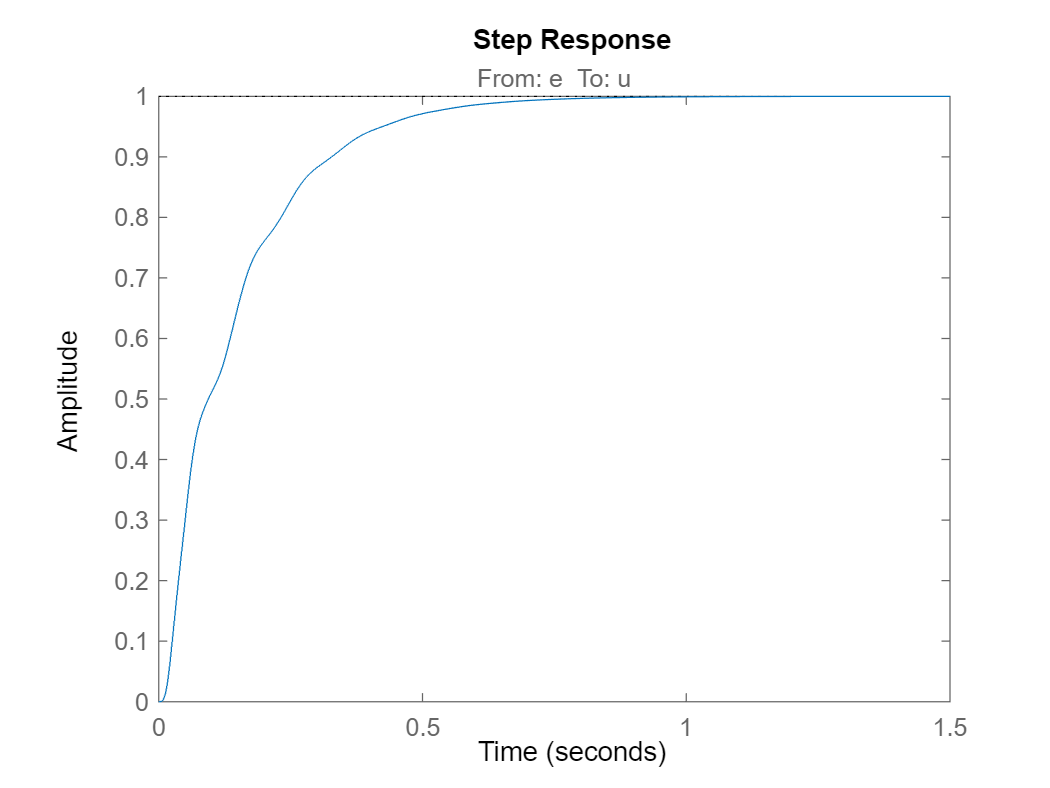

step(Cf*feedback(modello_posizione(1,1)*Ce,1))

I margini di stabilità

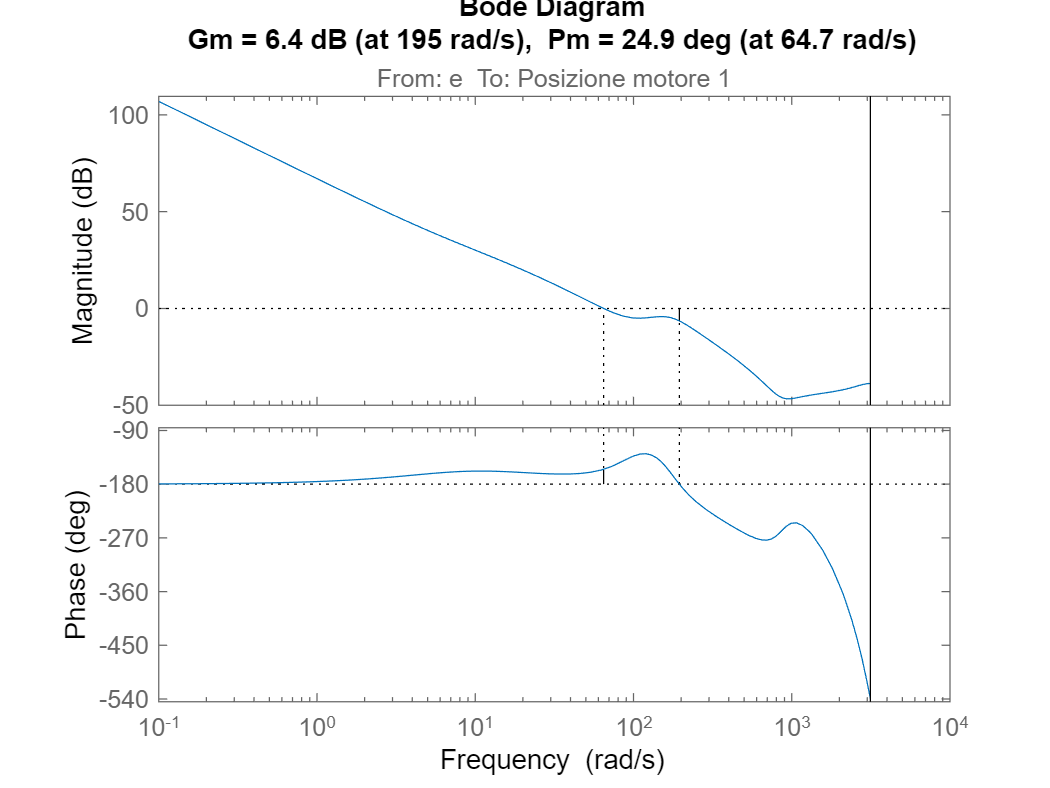

margin(modello_posizione(1,1)*Ce)

allmargin(modello_posizione(1,1)*Ce)

ans = struct with fields:
     GainMargin: [0 2.0900 86.3323]
    GMFrequency: [0 194.8150 3.1416e+03]
    PhaseMargin: 24.9059
    PMFrequency: 64.7386
    DelayMargin: 6.7145
    DMFrequency: 64.7386
         Stable: 1


I diagrammi di Bode

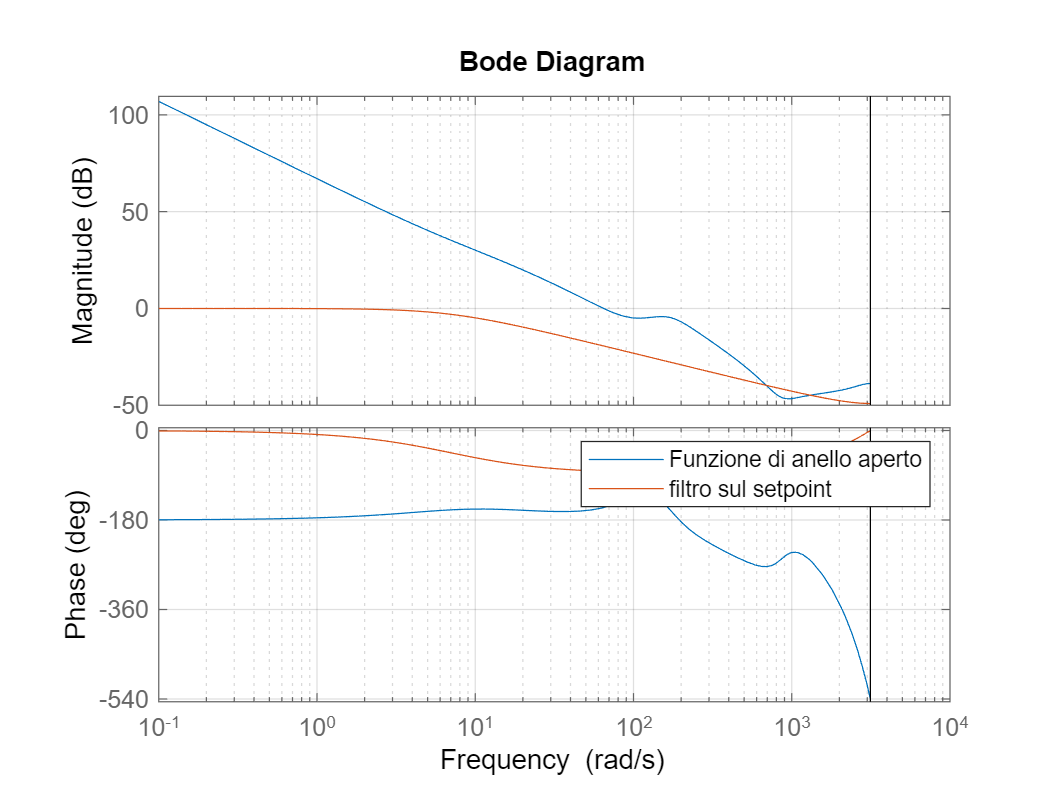

bode(modello_posizione(1,1)*Ce,Cf)
grid on
legend('Funzione di anello aperto','filtro sul setpoint')